# Inline Double Plunger 00

clearvars

## Outlet

Cv = 6

Cv = 6

Cd = 0.61

Cd = 0.6100

B = 0

B = 0

r = 0.00465*sqrt(Cv/Cd) %m

r = 0.0146

A = pi * r^2 %m2

A = 6.6815e-04

## Main

m_o_r = 1e-3 %m

m_o_r = 1.0000e-03

m_t_t = 2e-3 %m

m_t_t = 0.0020

m_t_r = m_o_r + m_t_t %m

m_t_r = 0.0030

m_A_t = pi*m_t_r^2 %m2

m_A_t = 2.8274e-05

## Outlet

o_o_A = A + m_A_t %m2

o_o_A = 6.9643e-04

o_o_r= sqrt(o_o_A/pi) %m

o_o_r = 0.0149

o_e_A = o_o_A * 5 %m2

o_e_A = 0.0035

o_e_r = sqrt(o_e_A/pi) %m

o_e_r = 0.0333

o_t_t = 5e-3 %m

o_t_t = 0.0050

o_t_r = o_e_r + o_t_t %m

o_t_r = 0.0383

## Main

m_r = o_t_r + 150e-3 %m

m_r = 0.1883

m_hp_A = pi*(m_r^2 - o_t_r^2) %m2

m_hp_A = 0.1068

m_lp_A = pi*m_r^2 %m2

m_lp_A = 0.1114

### Main Force Balance

HP = 1.5 %MPa

HP = 1.5000

LP = 1 %MPA

LP = 1

% Up direction is positive
F_hp = HP * m_hp_A * 1e3 %kN

F_hp = 160.1637

F_lp = LP * m_lp_A * 1e3 %kN

F_lp = 111.3824

F = F_hp - F_lp %kN

F = 48.7813

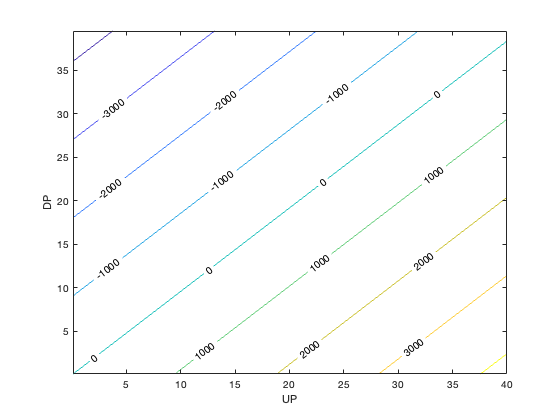


step = 0.1;
[UP,DP] = meshgrid(0.1:step:40,0.1:step:39.5);
figure(1)
F = (UP * m_hp_A - DP * m_lp_A) * 1e3; %kN
contour(UP,DP,F,'ShowText','on')
xlabel('UP'),ylabel('DP')

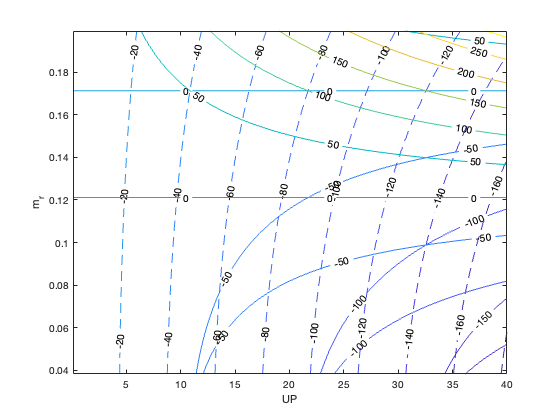



[UP,m_r] = meshgrid(0.1:step:40,o_t_r:1e-3:2e-1);
figure(2)
F = (UP .* (m_r.^2 - o_t_r^2) - 0.95 * UP .* m_r.^2) * pi * 1e3; %kN
contour(UP,m_r,F,'ShowText','on')
xlabel('UP'),ylabel('m_r')
hold on
F = (UP .* (m_r.^2 - o_t_r^2) - 0.99 * UP .* m_r.^2) * pi * 1e3; %kN
contour(UP,m_r,F,'--','ShowText','on')
F = (UP .* (m_r.^2 - o_t_r^2) - 0.90 * UP .* m_r.^2) * pi * 1e3; %kN
contour(UP,m_r,F,'-o','ShowText','on')